Load data

%192000 = 3x80x80 = size of each image
%change this if number of images is different from 16
num_images = 16;

I = zeros([19200 , num_images],"double");%vector to store the images
for i = 1:num_images
    %change this if path of image differs
    im = imread("data_fruit/image_" + string(i) + ".png"); %read the ith image
    I(:,i) = reshape(im,[19200, 1]); %reshape the image into a single vector
    %I(:,i) = rescale(I(:,i)); 
end

PCA

me = (sum(I,2)/size(I,2)); %mean
I = I - me; %origin shifted to mean
co = I*I' / size(I,2); %covariance matrix
[u, s] = eigs(co,4); % u=eigen vectors, diag(s)= eigenvalues

images of mean and eigenvectors

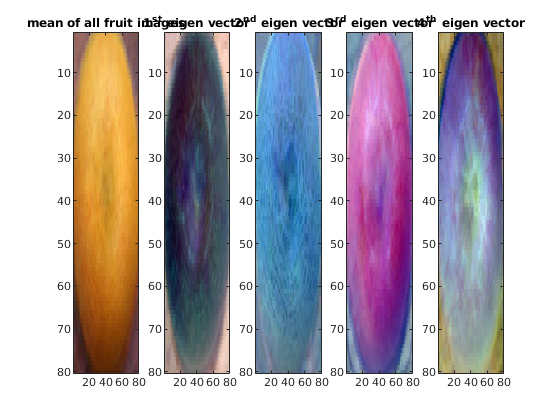

figure
subplot(1,5,1),imagesc(rescale(reshape(me,[80, 80, 3])))
title("mean of all fruit images")
subplot(1,5,2), imagesc(rescale(reshape(u(:,1),[80, 80, 3])))
title("1^{st} eigen vector")
subplot(1,5,3), imagesc(rescale(reshape(u(:,2),[80, 80, 3])))
title("2^{nd} eigen vector")
subplot(1,5,4), imagesc(rescale(reshape(u(:,3),[80, 80, 3])))
title("3^{rd} eigen vector")
subplot(1,5,5), imagesc(rescale(reshape(u(:,4),[80, 80, 3])))
title("4^{th} eigen vector")

Plot of first ten eigen-vectors

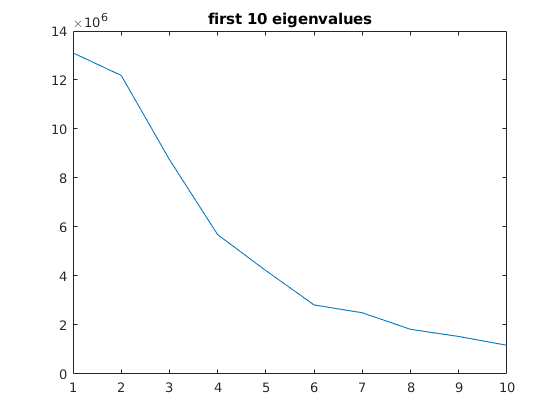

D = eigs(co,10);
figure
plot(D)
title("first 10 eigenvalues")

projections

The closest representation will be the projection of the image on the vector space formed by the four eigen vectors

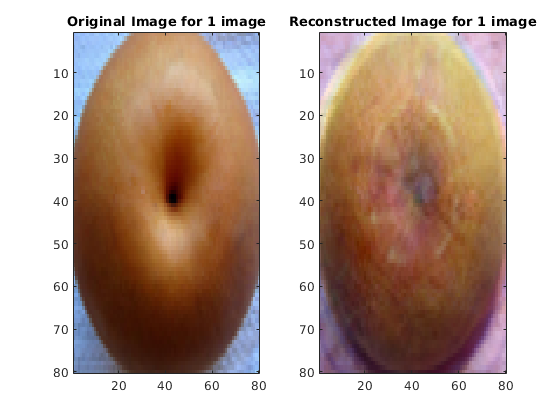

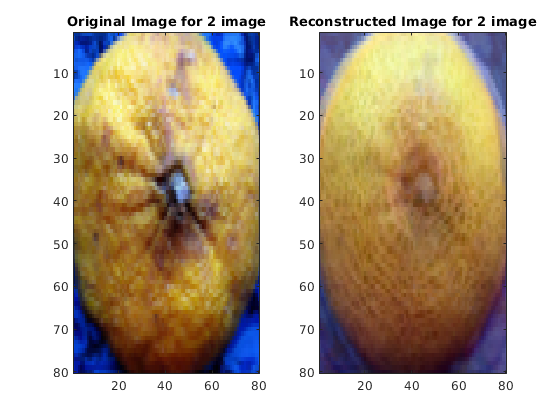

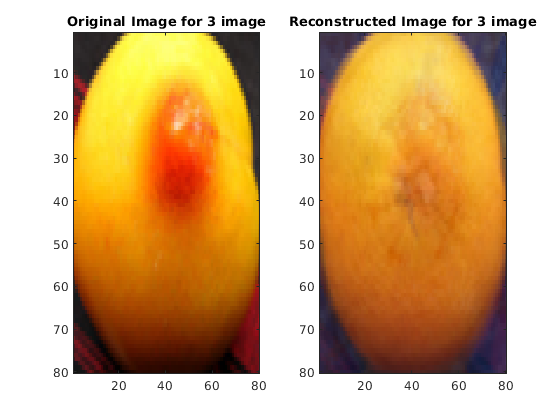

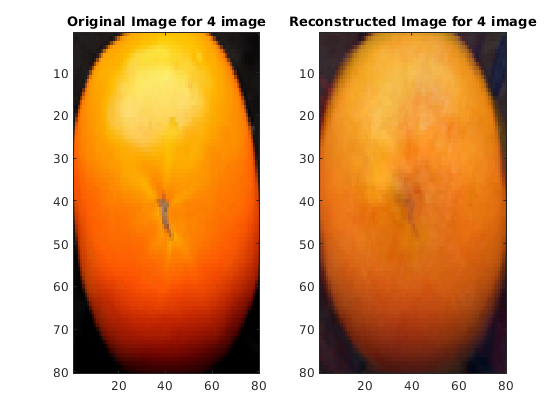

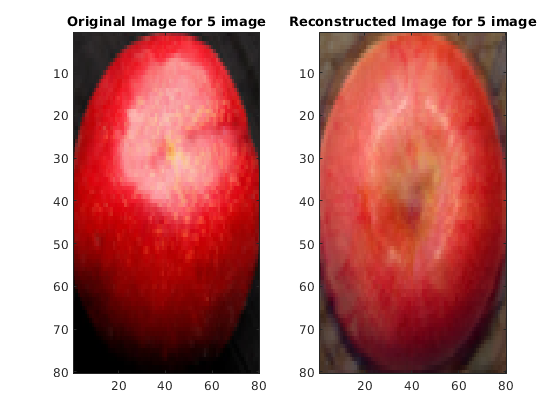

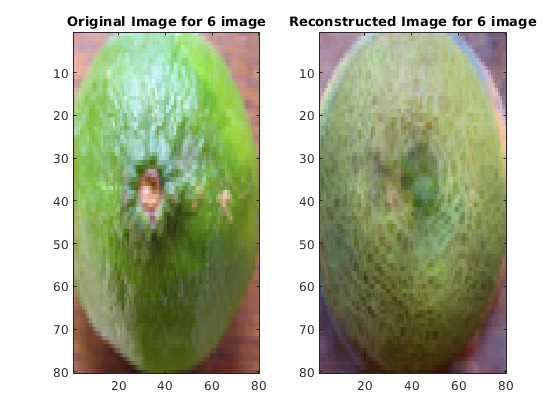

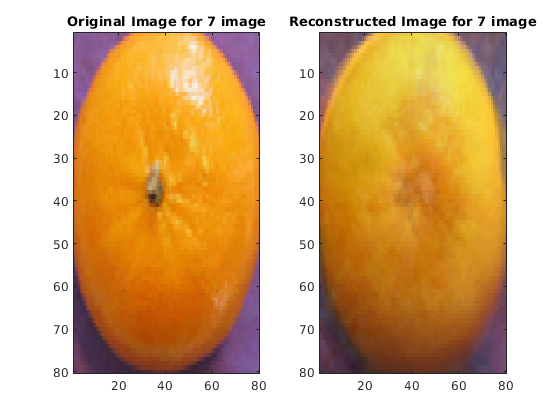

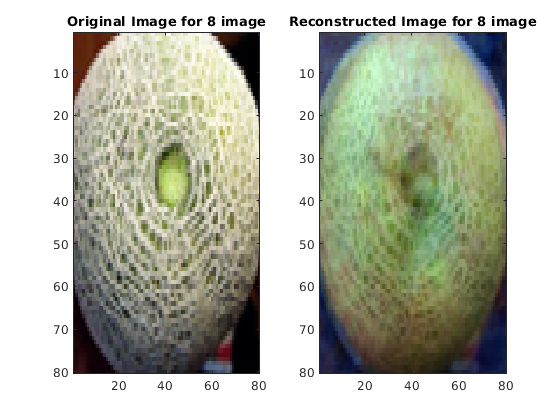

weights = u' * I; % dot product of the image on the smaller space
re_I = u*weights+me; %the reconstruction is simply weights * eigen_vector + mean. Note that I = Iamge-Mean
for i=1:num_images %Plotting
    figure
    subplot(1,2,1), imagesc(rescale(reshape(I(:,i)+me,[80, 80,3]))) %original image
    title("Original Image for "+num2str(i) + " image")
    subplot(1,2,2), imagesc(rescale(reshape(re_I(:,i),[80, 80,3])))
    title("Reconstructed Image for "+num2str(i) + " image")
end

Random Fruits from normal distribution

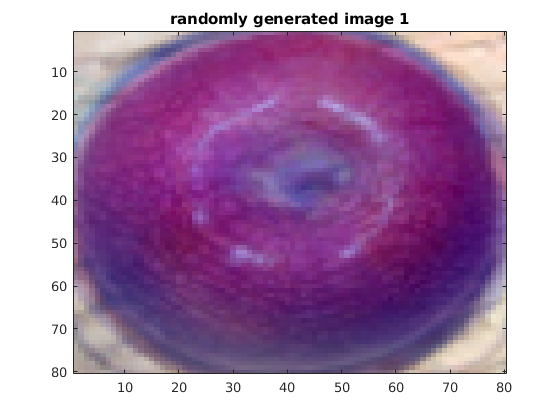

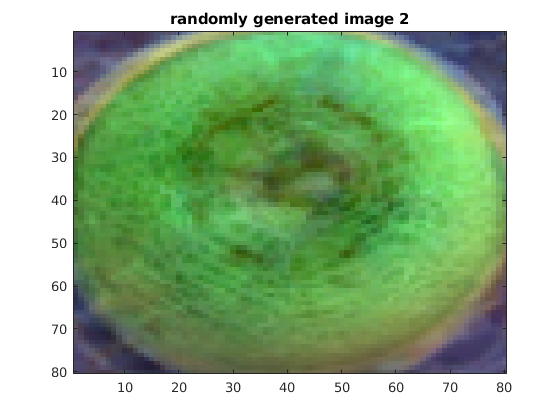

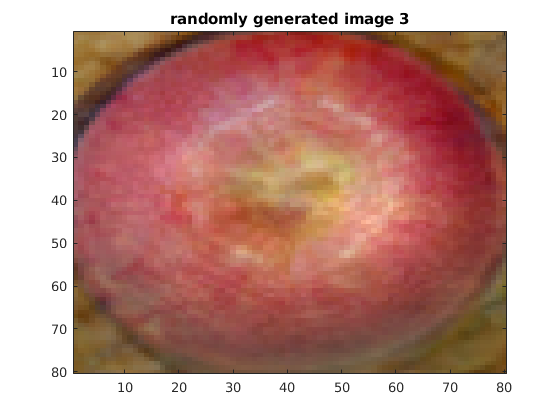

rng(4)
for i=1:3
    w = randn(4,1)*(rand+0.1)*norm(me);
    new_image = u*w+me;
    figure, imagesc(rescale(reshape(new_image,[80, 80,3]))) 
    title("randomly generated image "+num2str(i))
end